# Shallow-curved shell structure with geometric nonlinearities

See [1] for the details of this model, and [2] the description of this example.

[1] Jain, S., & Tiso, P. (2018). Simulation-free hyper-reduction for geometrically nonlinear structural dynamics: a quadratic manifold lifting approach. *Journal of Computational and Nonlinear Dynamics*, *13*(7), 071003. [https://doi.org/10.1115/1.4040021](https://doi.org/10.1115/1.4040021)

[2] Cenedese, M., Marconi, J., Haller, G., & Jain, S. (2023). Data-assisted non-intrusive model reduction for forced nonlinear finite elements models. Preprint: [arXiv: 2311.17865](https://arxiv.org/abs/2311.17865) 

The finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

See the `README` of the main repository to retrieve simulations data.

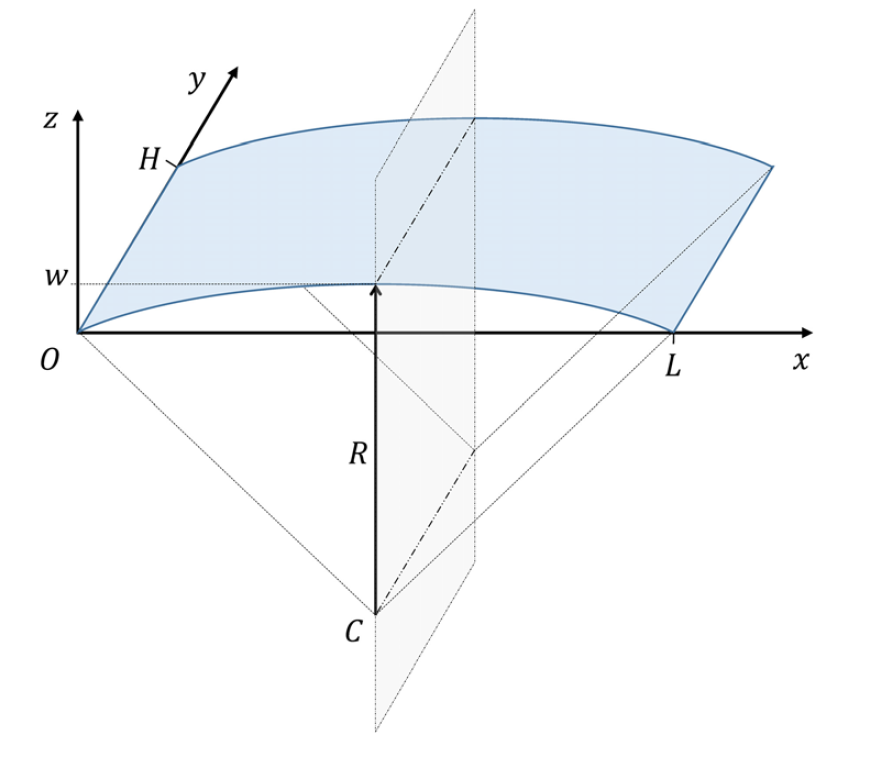

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}   & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}   \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

clearvars 
close all
clc

% Setup colors
colors = colororder; colSSMT = 5; colSSML = 7; colFOM = 1;

## Generate model

Building FE model


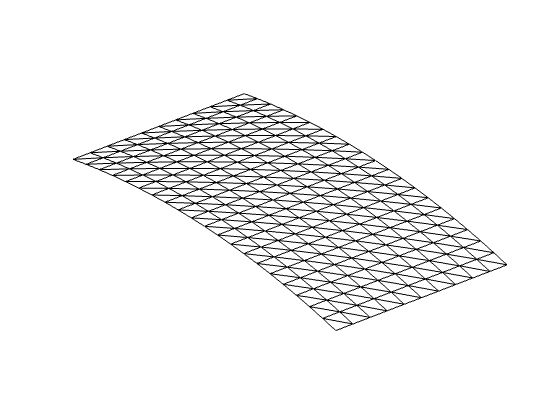

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


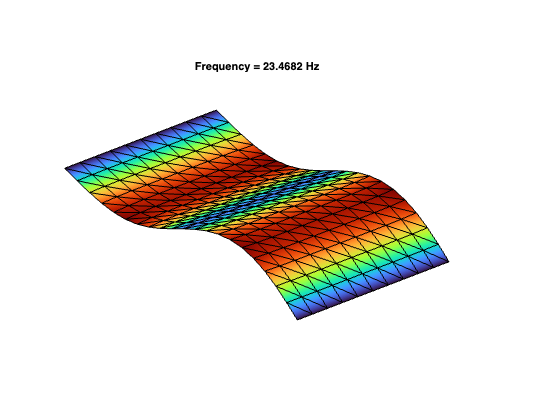

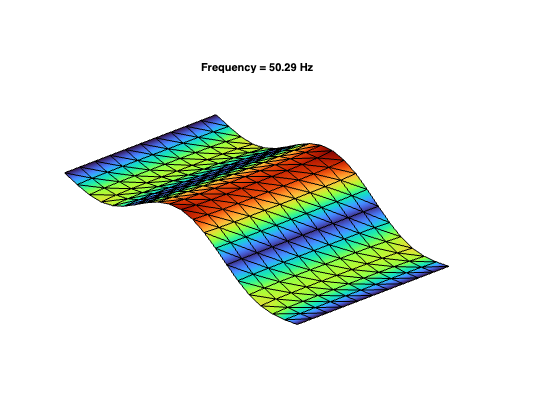

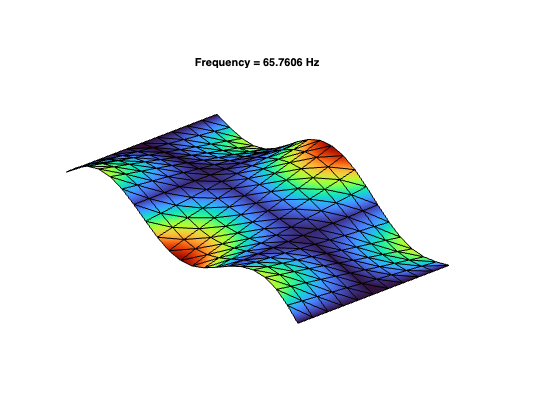

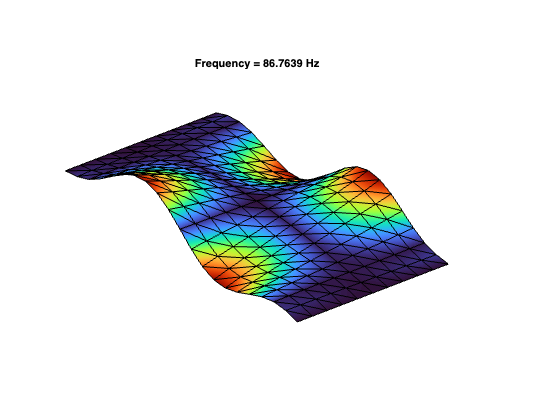

Using Rayleigh damping


a =    8.6312e-06
      0.40215


Assembling external force vector
Getting nonlinearity coefficients
Loaded tensors from storage
Total time spent on model assembly = 00:00:13


nDiscretization = 10; % Discretization parameter (#DOFs is proportional to the square of this number)
[M,C,K,fnl,f_0,outdof,Model] = buildModel(nDiscretization);

n = length(M); % number of degrees of freedom
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 1320


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 2640


DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
% set(DS.Options,'Emax',5,'Nmax',10,'notation','tensor')

## Linear modal analysis

if ~isfile('linpart.mat')
    m = 10;
    [W,A,V,lambda] = linearpart(M,C,K,m);
    save('linpart.mat',"W","A","V","lambda")
else
    load('linpart.mat')
end

## Define master modes and linear part of the dynamics

We initialize the base properties of the SSM, i.e., its linear part, which we know from the linear dynamics of the model. In this case, we target the slow two-dimensional SSM of the system. 

masterModes = [1 2]; % Modal displacements and modal velocities
Ve = V(:,masterModes); % Mode shape
We = W(masterModes,:); % Projection to mode shape
Ae = full(We*A*Ve) % Reduced, linearized dynamics

Ae =             0            1
       -21743     -0.58982


SSMDim = length(masterModes);

displacementVector = zeros(1,n); displacementVector(outdof) = 1;
loadVector = f_0;  %  could also be set as modal ones

## Load static analysis and plot

We characterize the linear and nonlinear regimes via a static analysis, which serves to pick appropriate initial conditions for the trajectories we need to learn the SSM from data.

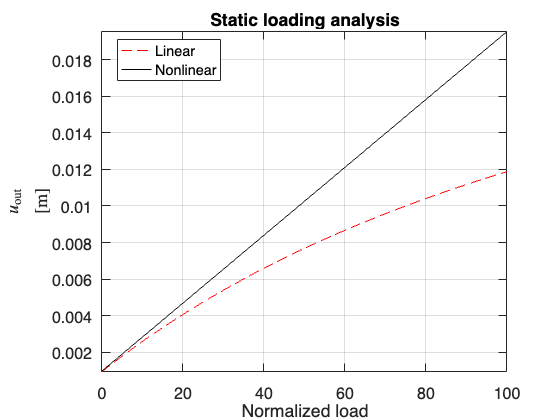

load("StaticDisplacements.mat")
nsteps = size(uNonlinear,2);
loadCoefficients = linspace(0,100,nsteps);

% Define observed deformation 
uNonlinearOut = uNonlinear(outdof,:);
uLinearOut = uLinear(outdof,:);
relativeDispDiff = 100*abs(uNonlinearOut-uLinearOut)./abs(uNonlinearOut);

customFigure;
plot(loadCoefficients,uNonlinearOut,'r--','DisplayName','Linear')
plot(loadCoefficients,uLinearOut,'-k','DisplayName','Nonlinear')
legend('location','best')
ylabel('$$u_{\mathrm{out}}$$ [m]','Interpreter','latex'); 
xlabel('Normalized load'); 
title('Static loading analysis');
axis tight


Z = [uNonlinear; zeros(n,nsteps)];

Pick up two initial trajectories that has high expected nonlinear content

indIC = [nsteps, nsteps-1];
IC = Z(:,indIC);
indTrain = 1;
indTest = 2;

Define the linear regime at 0.05 % relative displacement

linearDisplacementReference = uNonlinearOut(sum(relativeDispDiff<(0.05))+1);
nonlinearDisplacementReference = max(abs(uNonlinearOut(indIC)));
desiredAmplitudeDecay = nonlinearDisplacementReference/linearDisplacementReference;

## **Generate decaying trajectories via time integration**

We define observables and timescales. The computation of integration time is estimated from the linear decay that gets from the defined nonlinear amplitude to linear regime. We set the sampling time to capture approximately a fixed number points per period on the faster time scale. Then, we integrate using the initial conditions we obtained from the static analysis. Here, we use a pre-computed data set to avoid excessive computations.

observable = @(x) x; % Observe the full phase space
slowTimeScale = 2*pi/abs(lambda(1));
fastTimeScale = 2*pi/abs(lambda(round(SSMDim/2)));
% The computation of integration time is estimated from the linear decay 
% that gets from the nonlinear amplitude to linear regime.
numberPeriodsSlow = floor(log(desiredAmplitudeDecay)/...
    (2*pi*(-real(lambda(1))/abs(lambda(1)))))

numberPeriodsSlow =    201


endTime = numberPeriodsSlow*slowTimeScale;
% Set the sampling time to capture approximately 100 points per period on 
% the faster time scale
numberPeriodsFast = floor(endTime/fastTimeScale);
numberPointsPerPeriod = 100;
nSamp = numberPeriodsFast*numberPointsPerPeriod+1;
dt = endTime/(nSamp-1);
% xData = integrateTrajectoriesGalphaDirect(Model, DS, endTime, IC, nSamp, observable);
% % xData = integrateTrajectoriesNewmarkDirect(Model, DS, endTime, IC, nSamp, observable);
% DataInfo = struct('nElements', Model.Mesh.nElements, 'loadShape', loadShape);
% save('dataVKDecay2DGalpha.mat', 'DataInfo', 'xData', 'dt', 'endTime', 'nSamp')
load("../../data/vonkarmanshell/dataVKDecay2DGalphaStatic.mat")

## Visualize data

% This step is here not mandatory as we know that the SSM exists in the
% phase space (no embedding needed)
xData = coordinatesEmbedding(xData, SSMDim, 'ForceEmbedding', 1);

The embedding coordinates consist of the measured states.


Data filtering: We need to make sure that the data that we use to identify the manifold lies close to it. We can do this by plotting a spectrogram of the observables of interest. In general, there may be many vibratory modes present at first, but the faster ones quickly die out.

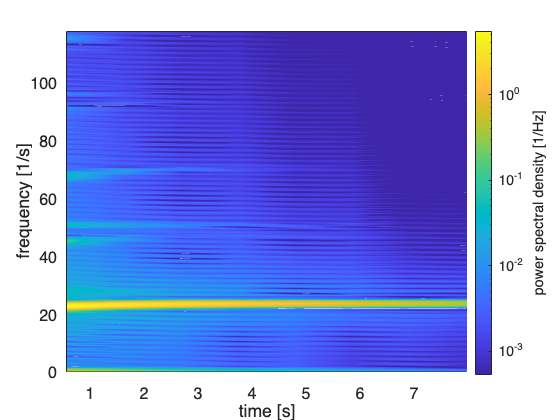

showSpectrogram(xData(indTrain,:), outdof);
ylim([0,abs(lambda(1))/2/pi*5])

We plot theobservables of interest over time for closer inspection. 

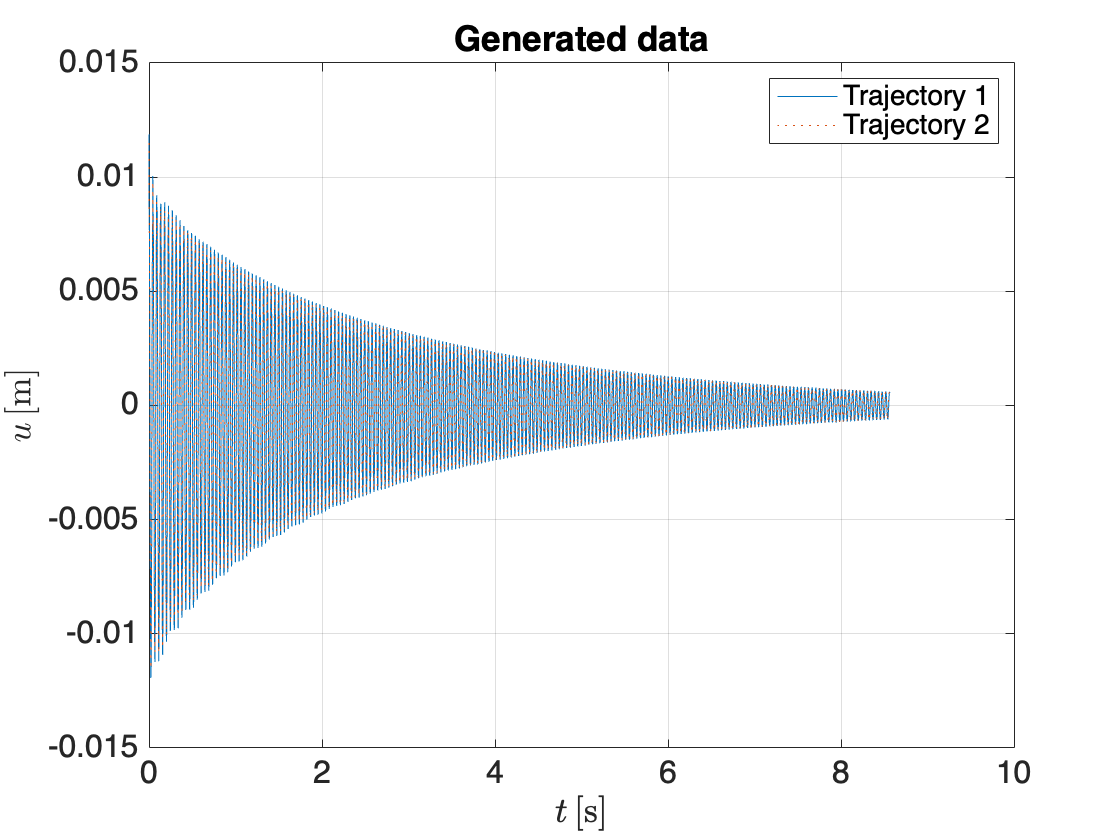

customFigure();
plot(xData{1,1}, xData{1,2}(outdof,:), xData{2,1}, xData{2,2}(outdof,:), ':');
xlabel('$t \, [$s$]$','Interpreter','latex'); ylabel('$u \, [$m$]$','Interpreter','latex'); 
legend({'Trajectory 1', 'Trajectory 2'})
title('Generated data')

## Truncate transient data from trajectories

We must however remove the first transient to fulfill the assumption that trajectories lie close to the SSM. We keep only the time interval |sliceInt|.

sliceInt = [5*slowTimeScale, endTime];
xDataTrunc = sliceTrajectories(xData, sliceInt);

## Datadriven manifold fitting

The measured trajectories are initialized to lie close to the manifold of interest that is tangent at the origin to the eigenspace spanned by the columns of $\mathbf{V}_e$. 

As we also know the projection $\mathbf{W}_e$ to this eigenspace, we define the modal coordinates as $\mathbf{y} = \mathbf{W}_e \mathbf{x}$. These are the reduced coordinates for our graph style parametrization of the manifold, gauranteed to exists near the origin. We then use the data to learn the nonlinear feature of the manifold geometry, represented via polynomials. Indeed, we seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$\mathbf{x} = \mathbf{V}_e \mathbf{y}  + \mathbf{H}  \mathbf{\phi}_{m,2:M}(\mathbf{y} )$,

where the function $\mathbf{\phi}_{m,2:M}(\mathbf{y})$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $\mathbf{y}$. From SSM theory, the tangent space of the manifold is $\mathbf{V}_e$. The coefficients $\mathbf{H}$are obtained via least squares regression.

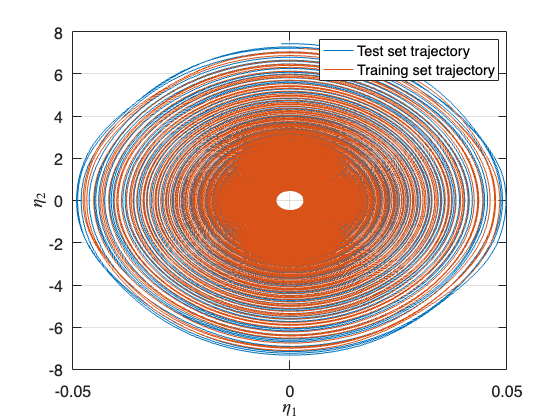

SSMOrder = 7;

% Get projection or modal coordinates 
SSMDim = size(Ve,2);
yDataTrunc = xDataTrunc;
nTraj = size(xDataTrunc,1);
for iTraj = 1:nTraj
    yDataTrunc{iTraj,2} = We*xDataTrunc{iTraj,2};    
end

% Plot reduced coordinates
plotReducedCoordinates(yDataTrunc);
legend({'Test set trajectory', 'Training set trajectory'})

if SSMDim>2
   view(3) 
end

% Compute nonlinear part of the parametrization
IMInfo = IMGeometry(xDataTrunc(indTrain,:), SSMDim,SSMOrder,...
         'reducedCoordinates',yDataTrunc(indTrain,:),'Ve',Ve,'outdof',outdof); 
IMInfo.chart.map = @(x) We*x;                          

% Parametrization error on test trajectory
normedTrajDist = computeTrajectoryErrors(liftTrajectories(IMInfo,...
    yDataTrunc), xDataTrunc);
staticNMTE = mean(normedTrajDist(indTest))*100; % in percentage

disp(['Reconstruction error = ' num2str(staticNMTE) '%'])

Reconstruction error = 1.0349%


## Plot SSM

We plot the SSM geometry in different coordinates.

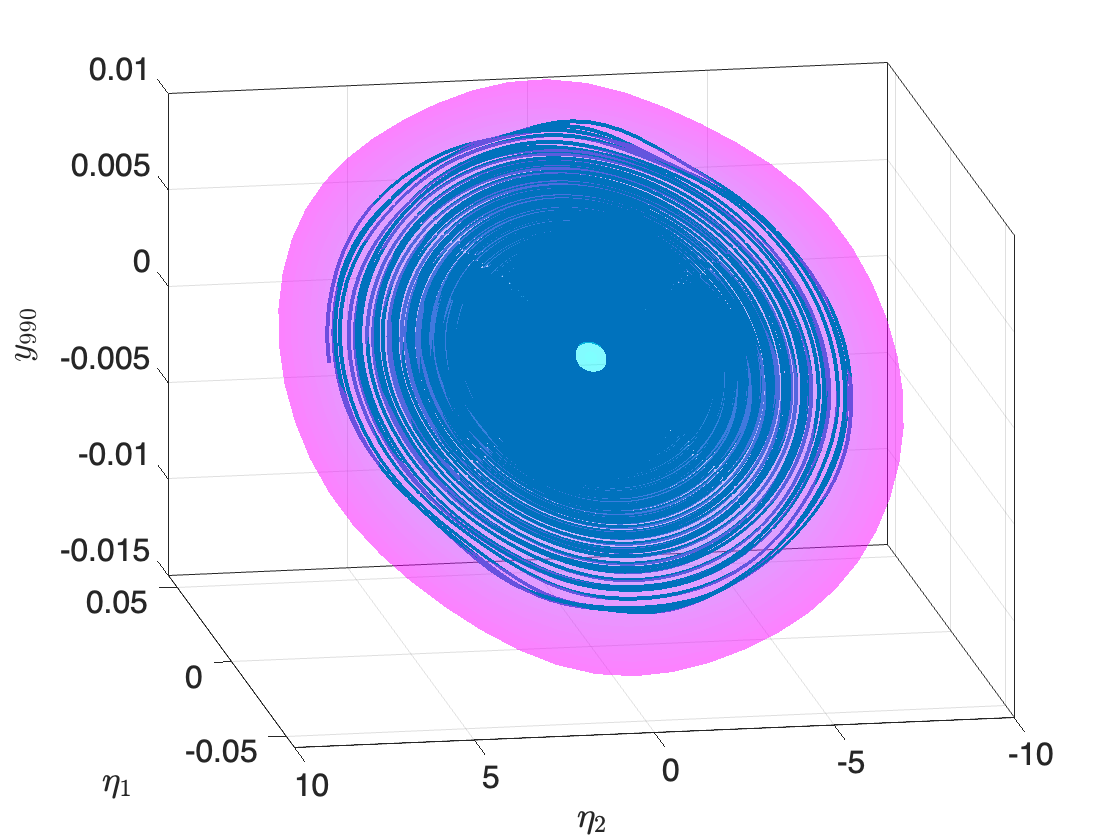

idxPlot = [outdof]; % 3D Plot: eta_1, eta_2 and idxPlot coordinate
plotSSMandTrajectories(IMInfo, idxPlot, xDataTrunc(indTest,:), yDataTrunc(indTest,:))
view(-100,20); legend('off')

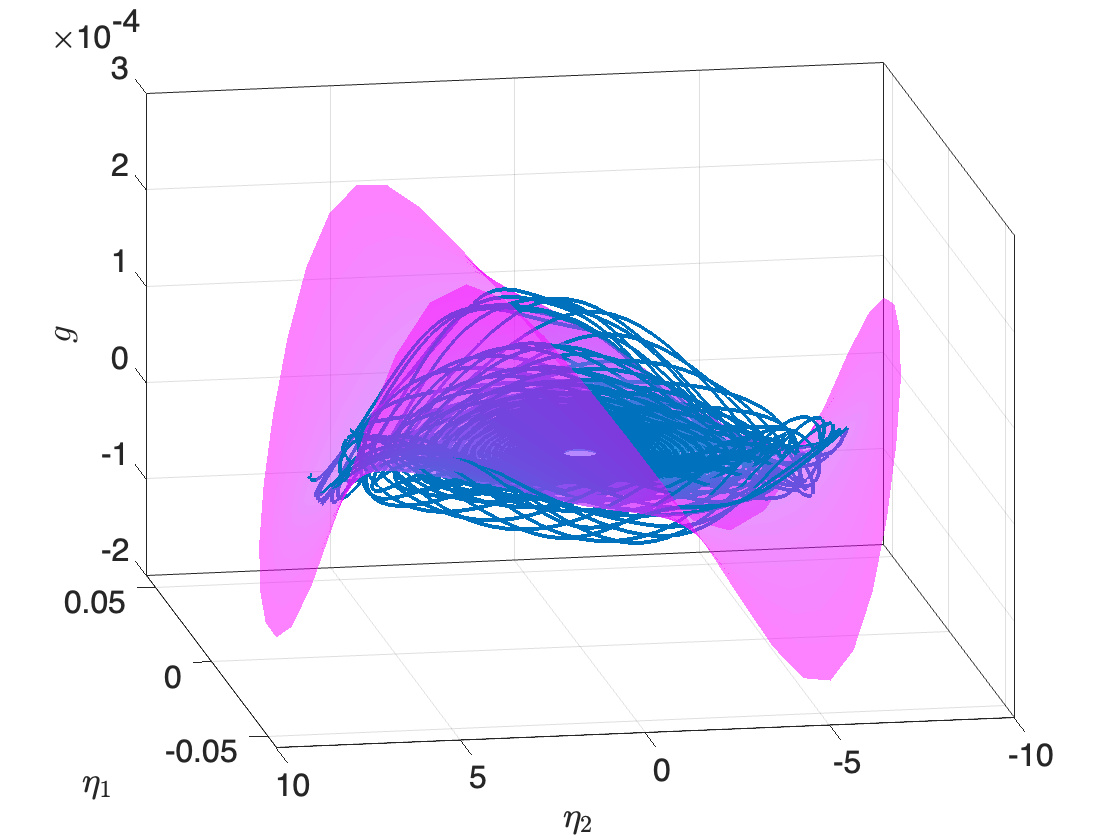

gPlot = @(x) W(5,:)*x; % 3D Plot: eta_1, eta_2 and gPlot(x) 
plotSSMandTrajectories(IMInfo, gPlot, xDataTrunc(indTest,:), yDataTrunc(indTest,:))
view(-100,20); legend('off')

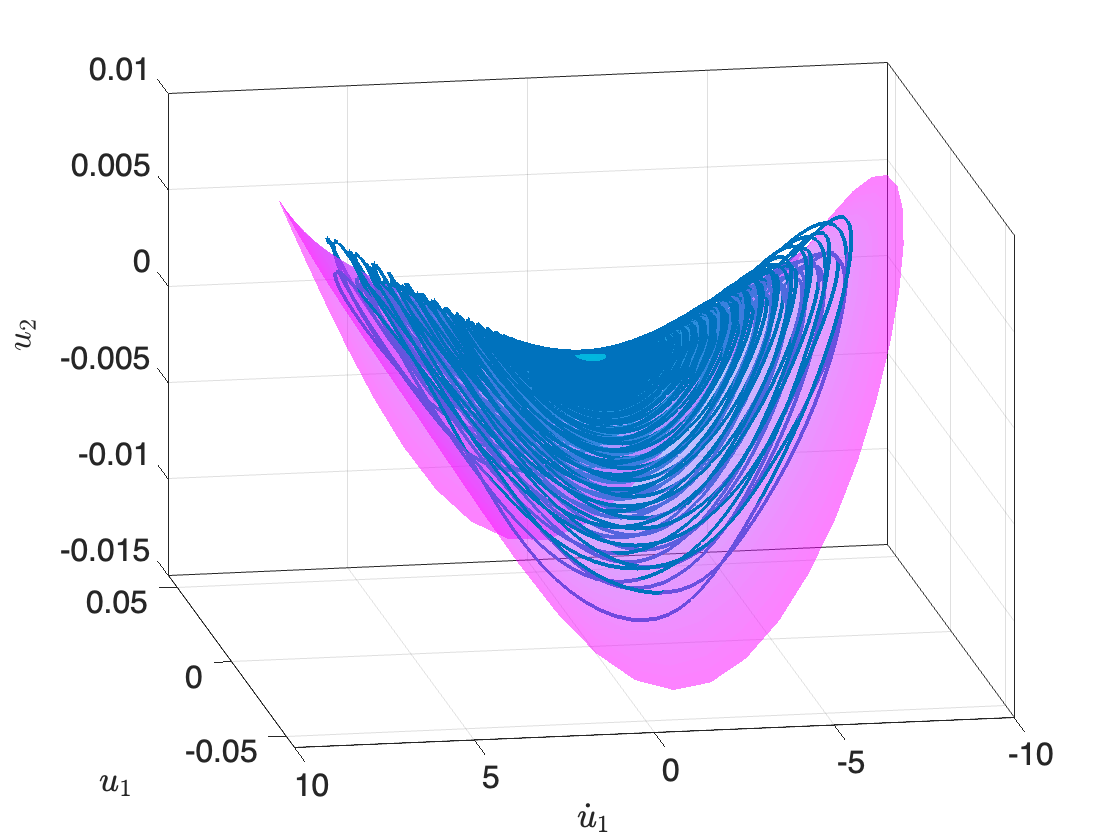

gPlot = @(x) W([3],:)*x; % 3D Plot with the three values of gPlot(x) 
plotSSMandTrajectories(IMInfo, gPlot, xDataTrunc(indTest,:), yDataTrunc(indTest,:))
view(-100,20); legend('off')
xlabel('$u_1$','interpreter','latex')
ylabel('$\dot{u}_1$','interpreter','latex')
zlabel('$u_2$','interpreter','latex')

## Reduced dynamics on the manifold

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsMech` finds the dynamics (considering that we know the linear part)

$\dot{\mathbf{y}}= \mathbf{A}_e \mathbf{y}  + \mathbf{H}_r  \mathbf{\phi}_{m,2:M}(\mathbf{y} )$,

where $\mathbf{\phi}(\mathbf{y})$ again computes a vector of all monomials of $\mathbf{u}$, and $\mathbf{H}_r$ is a matrix of polynomial coefficients of the form


$$\mathbf{H}_r = \left[\matrix{  \mathbf{0} \cr  \mathbf{W}_r } \right]$$


Then, we find from data the extended normal form, which expedites system characterization and computation of periodic forced responses.

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          2.77856                            24
     1           3          1.87811     0.00416699           21.5  
     2           4          1.32201              1           12.5  
     3           6          1.15664       0.446756           4.69  
     4           7           1.0076              1           1.87  
     5           8          0.97563              1          0.358  
     6           9         0.974841              1          0.356  
     7          10         0.969736              1          0.518  
     8          11         0.966971              1           0.54  
     9          12         0.961994              1          0.614  
    10          13         0.956859              1           0.61  
    11          14

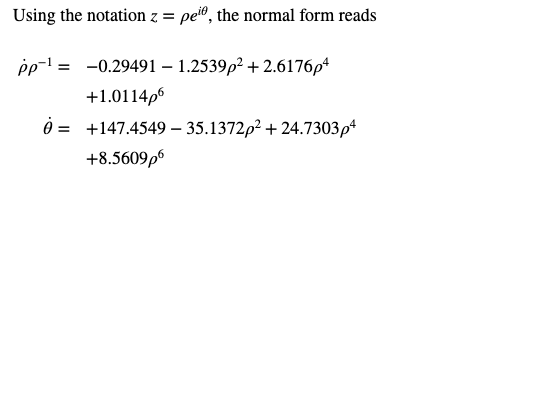

ROMOrder = 7;

RDInfo = IMDynamicsMech(yDataTrunc(indTrain,:), ...
    'R_PolyOrd', 1,'N_PolyOrd', ROMOrder, 'style', 'normalform', ...
    'R_coeff',Ae,'rescale',1,'MaxIter',5e3);


% We transform the truncated initial condition of our test trajectory according to 
% the obtained change of coordinates, and integrate our reduced order evolution rule 
% to predict the development of the trajectory. 
[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, xDataTrunc);

% Evaluation of reduced dynamics
% The error NMTE is computed as the average distance of the predicted trajectory 
% to the measured one in the full state space.
normedTrajDist = computeTrajectoryErrors(yRec, xDataTrunc);
NMTE = mean(normedTrajDist(indTest))*100;
disp(['Normalized mean trajectory error = ' num2str(NMTE) '%'])

Normalized mean trajectory error = 6.3316%


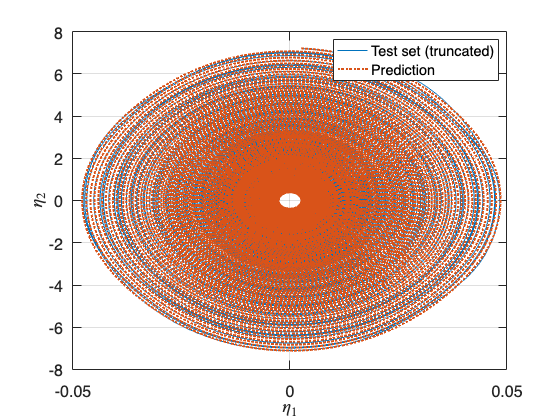


% We plot the true test set trajectory in the reduced coordinates and compare it to the prediction. 
plotReducedCoordinates(yDataTrunc(indTest,:), etaRec(indTest,:))
legend({'Test set (truncated)', 'Prediction'})

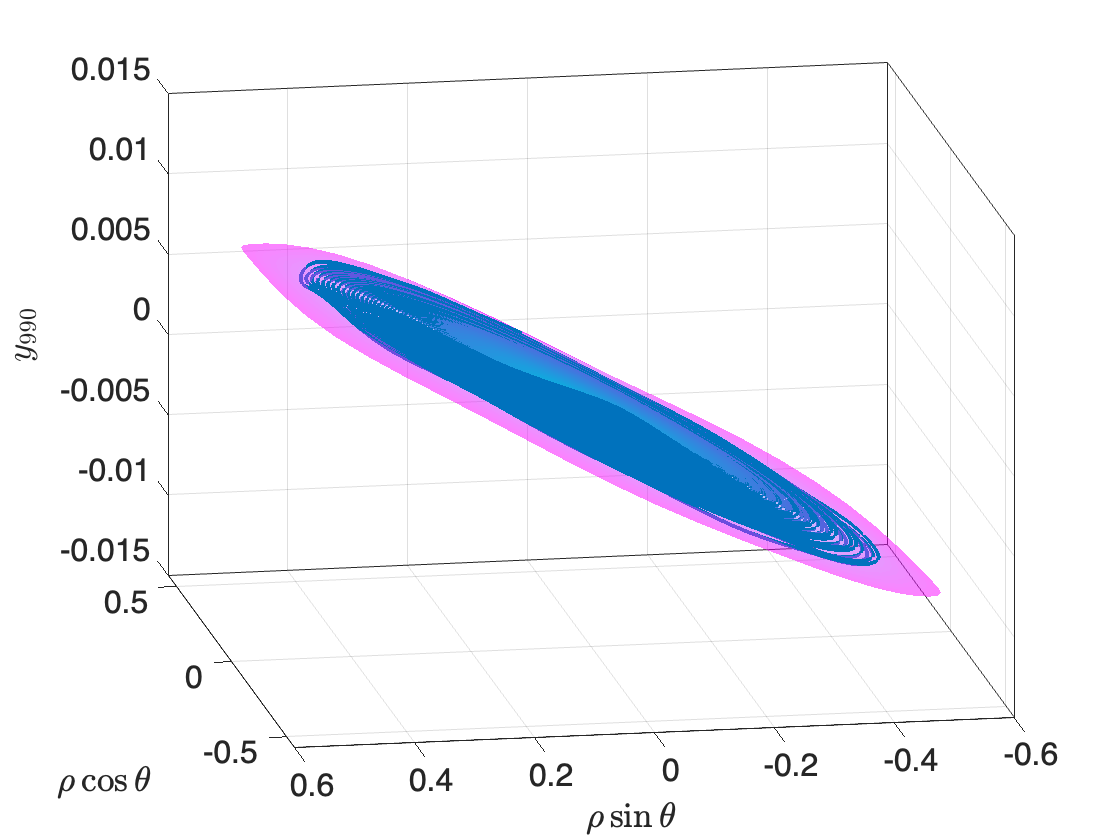

if size(Ae,1)==2
    % Plot SSM with trajectories in the normal form reduced coordinates
    plotSSMandTrajectories(IMInfo, outdof, xDataTrunc(indTest,:), ...
        zRec(indTest,:), 'NFT', RDInfo.transformation.map)
    view(-100,20); legend('off')
else
    view(3)
end

We plot the model predictions in physical coordinates. The reduced model seems to do well on previously unseen data, provided that it is close to the manifold.

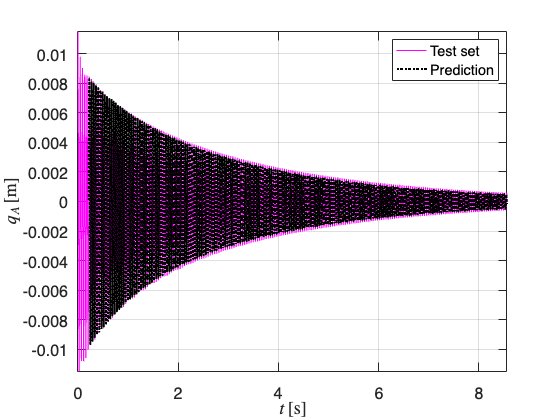

plotTrajectories(xData(indTest,:), yRec(indTest,:), 'm','PlotCoordinate', outdof(1), 'DisplayName', {'Test set', 'Prediction'})
xlabel('$t \, [$s$]$','Interpreter','latex')
ylabel('$q_A \, [$m$]$','Interpreter','latex')

## Adding forcing to the ROM

Outer directions: either consider all outer modes or a subset

nModes = size(V,2);
outerModes = setdiff(1:nModes,masterModes);
Vo = V(:,outerModes); 
Wo = W(outerModes,:); Lo = full(Wo*A*Vo);

Forcing vector

forcingVectors = [zeros(n,1); M\loadVector];

Construct time periodic SSM model

[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1,...
         'forcingVectors',forcingVectors,'We',We,'Lo',Lo,'Vo',Vo, 'Wo',Wo);

## Generate Frequency Responses

We compute them also with SSMTool in order to compare the results (see the papers above for additional validations and comparisons).


 Run='SSMLearnFRC.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          3.70e-04  2.09e+02    0.0    0.0    0.0
   1   1  1.00e+00  8.40e-04  5.48e-08  2.09e+02    0.0    0.0    0.0
   2   1  1.00e+00  1.12e-07  2.88e-15  2.09e+02    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om         rho1          th1          eps
    0  00:00:00   2.0867e+02      1  EP      1.4745e+02   1.1416e-01   5.3150e+00   1.0000e-01
   10  00:00:00   2.0702e+02      2          1.4625e+02   1.8703e-01   6.3141e+00   1.0000e-01
   14  00:00:00   2.0700e+02      3  FP      1.4623e+02   1.8456e-01   6.4671e+00   1.0000e-01
   14  00:00:00   2.0700e+02      4  SN      1.4623e+02   1.8456e-01   6.4671e+00   1.0000e-01
   20  00:00:00   2.0718e+02      5          1.4634e+02   1.6262e-01   6.8494e+00   1.0000e-01
   27  00:00

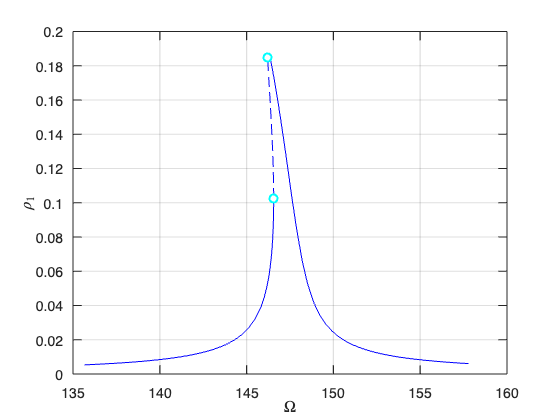

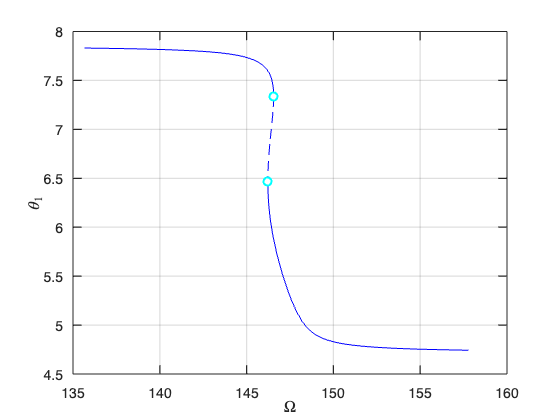


 Run='SSMLearnFRC.ep.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.97e-03  2.09e+02    0.0    0.0    0.0
   1   1  1.00e+00  1.89e-03  1.16e-06  2.09e+02    0.0    0.0    0.0
   2   1  1.00e+00  4.36e-07  6.70e-14  2.09e+02    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om         rho1          th1          eps
    0  00:00:00   2.0866e+02      1  EP      1.4745e+02   1.4968e-01   5.1079e+00   2.0000e-01
   10  00:00:00   2.0472e+02      2          1.4464e+02   3.0103e-01   5.8985e+00   2.0000e-01
   19  00:00:00   2.0404e+02      3  SN      1.4414e+02   3.1763e-01   6.3740e+00   2.0000e-01
   19  00:00:00   2.0404e+02      4  FP      1.4414e+02   3.1763e-01   6.3740e+00   2.0000e-01
   20  00:00:00   2.0404e+02      5          1.4414e+02   3.1704e-01   6.3988e+00   2.0000e-01
   30  00

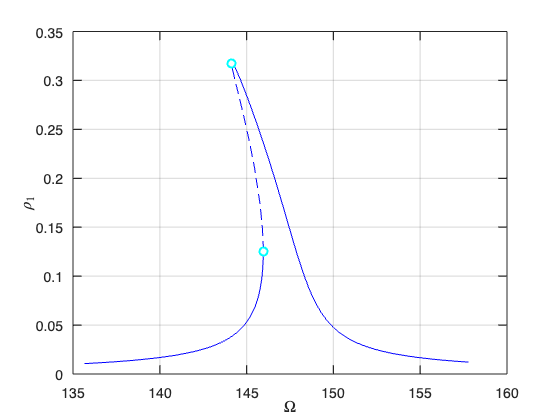

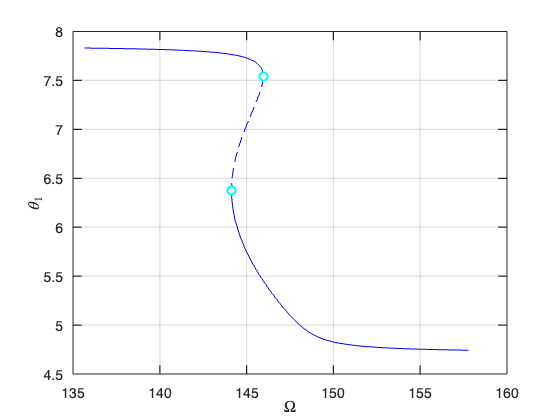

epsilon = [0.1 0.2];
mFreqs = [1];
resonantModes = [1 2];
omegaSpan = [0.92 1.07]*imag(lambda(1));
% SSMLearn
[FRCSSMLearn] = continuationFRCep(IMInfoF, RDInfoF, epsilon, omegaSpan,@(x) x(outdof,:), mFreqs,resonantModes, 'SSMLearnFRC');

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-03
modal damping ratio for 2 mode is 2.000000e-03
modal damping ratio for 3 mode is 2.269789e-03
modal damping ratio for 4 mode is 2.721500e-03
modal damping ratio for 5 mode is 2.909530e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
     -0.29491 +     147.45i
     -0.29491 -     147.45i
     -0.63196 +     315.98i
     -0.63196 -     315.98i
     -0.93785 +     413.19i
     -0.93785 -     413.19i
      -1.4836 +     545.15i
      -1.4836 -     545.15i
      -1.7341 +     596.01i
      -1.7341 -     596.01i

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     1
     0     2
     1     3
     

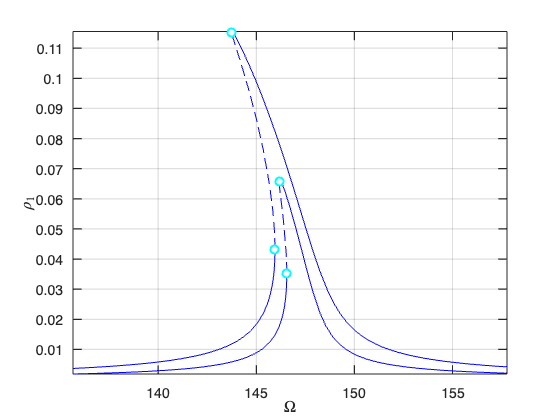

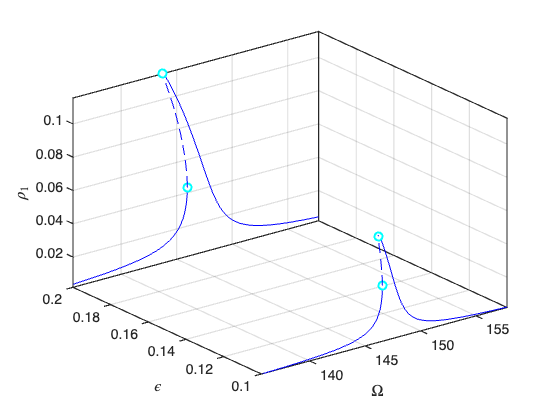

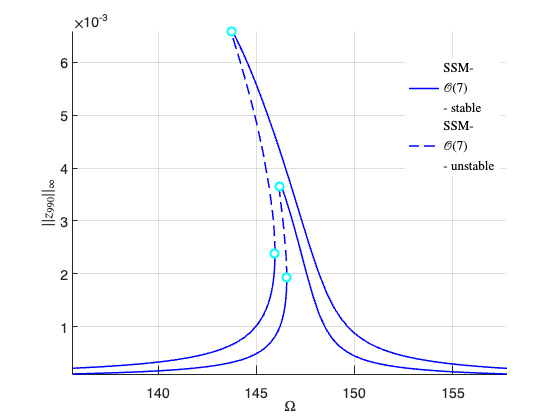

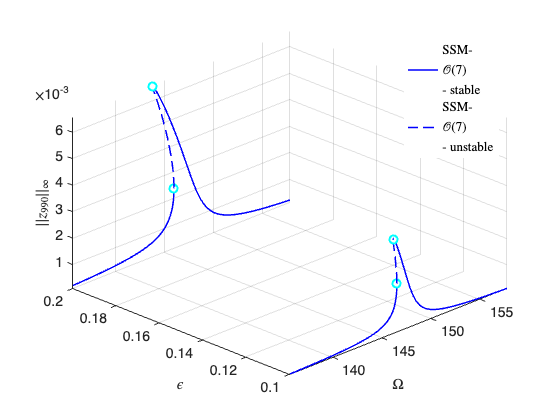

% SSMTool
FRCSSMTool = SSMToolFRCFE(M,C,K,fnl,f_0,outdof,epsilon,resonantModes,ROMOrder,omegaSpan,mFreqs,'SSMToolFRC');

## **Plot results**

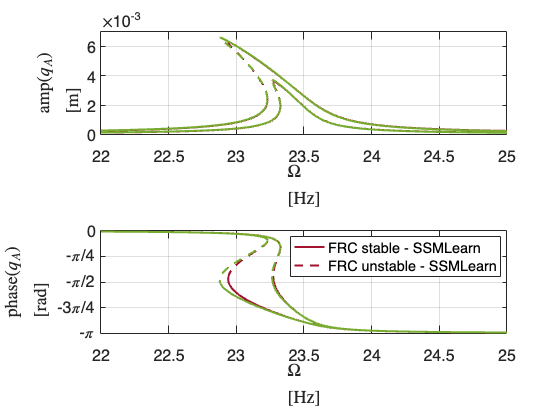

customFigure('subPlot',[2 1]); 
subplot(211)
plotFRC(FRCSSMLearn, colors(colSSML,:), '- SSMLearn','freqscale',2*pi)
plotFRC(FRCSSMTool, colors(colSSMT,:), '- Tool','freqscale',2*pi)
xlabel('$$\Omega$$ [Hz]','interpreter','latex')
ylabel('$$\mathrm{amp}(q_{A})$$ [m]','interpreter','latex')
legend('off')
%xlim([ceil(omegaSpan(1)*100)/100 floor(omegaSpan(2)*100)/100]/(2*pi))
xlim([22 25])
ylim([0 0.007])
subplot(212)
plotFRC(FRCSSMLearn, colors(colSSML,:), '- SSMLearn','y','Phase','freqscale',2*pi)
plotFRC(FRCSSMTool, colors(colSSMT,:), '- SSMTool','y','Phase','freqscale',2*pi)
xlabel('$$\Omega$$ [Hz]','interpreter','latex')
ylabel('$$\mathrm{phase}(q_{A})$$ [rad]','interpreter','latex')
ylim([-pi 0])
set(gca,'YTick',[-pi -3/4*pi -pi/2 -pi/4 0])
set(gca,'YTickLabel',{'-\pi', '-3\pi/4', '-\pi/2', '-\pi/4', '0'})
%xlim([ceil(omegaSpan(1)*100)/100 floor(omegaSpan(2)*100)/100]/(2*pi))
xlim([22 25])